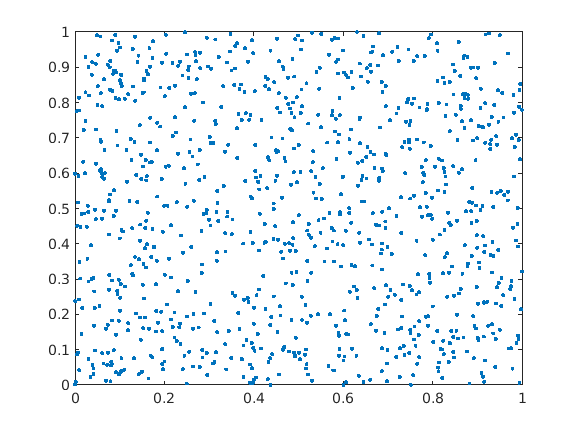

clear all;
close all;

a = 65539;
m = 2^31;
k = 1000;
x = zeros(1,k);
x(1) = 51;
for i=2:k
    x(i) = mod(a*x(i-1),m);
end
x = x/max(x);
xs1 = circshift(x,-1);
plot(x,xs1,'.');

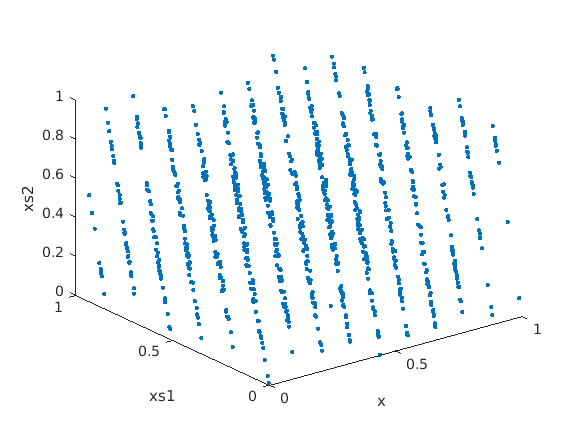

xs2 = circshift(x,-2);
plot3(x,xs1,xs2,'.');
xlabel('x');
ylabel('xs1');
zlabel('xs2');

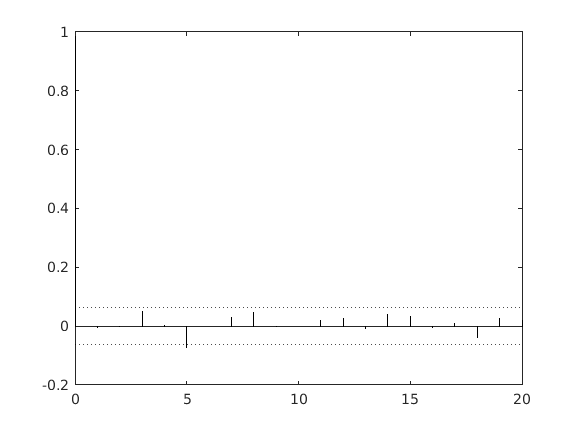

[acf,lags,bounds] = autocorr(x);
stem(lags,acf,'Marker','none','Color','k');
hold on
yline(bounds(1),':k');
yline(bounds(2),':k');
hold off